Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

Figura 1- Circuito base

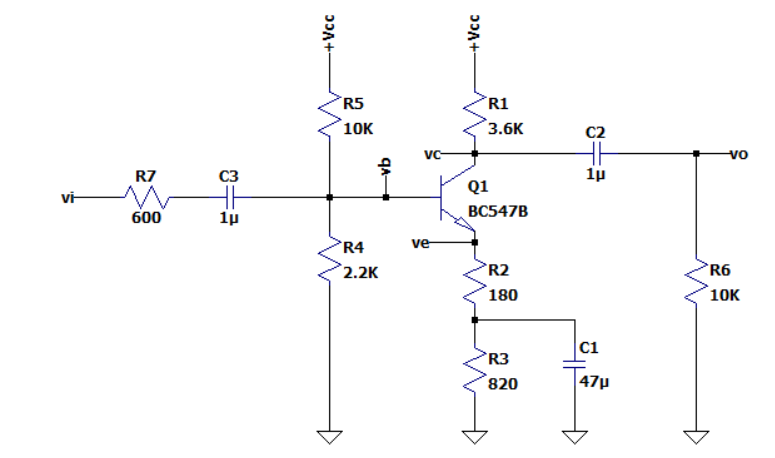

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

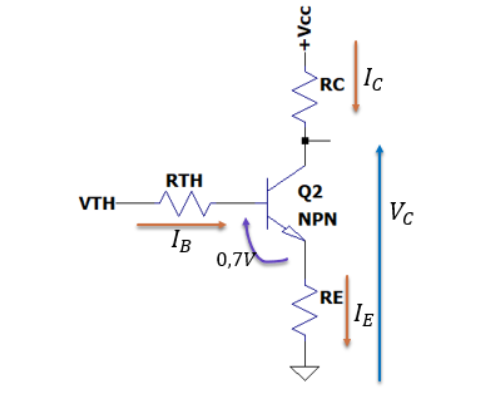

### Valores dos componentes:

R5 = 10e+3;%%Rth
R4 =2.2e+3;%%Rth
RE = 1e+3;%% R2+R3
Vcc = 18;%%Variavel de entrada
B = 290; % Beta para o calc
Vbe = 0.7; 
Vce = 5; %data sheet


### Equivalentes de TH

Vth = (R4/(R5+R4))*Vcc

Vth = 1.8033

Rth = ((1/R5)+(1/R4))^-1

Rth = 1.8033e+03

### Correntes

Ib = (Vth-Vbe)/(Rth+RE*(B+1))

Ib = 3.7680e-06

Ic = (B+1)*Ib

Ic = 0.0011

Ie = Ic

Ie = 0.0011

### Tensões CC

Vb = Vth

Vb = 1.8033

Ve = RE*Ie

Ve = 1.0965

Vc = Vce+Ve

Vc = 6.0965

## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

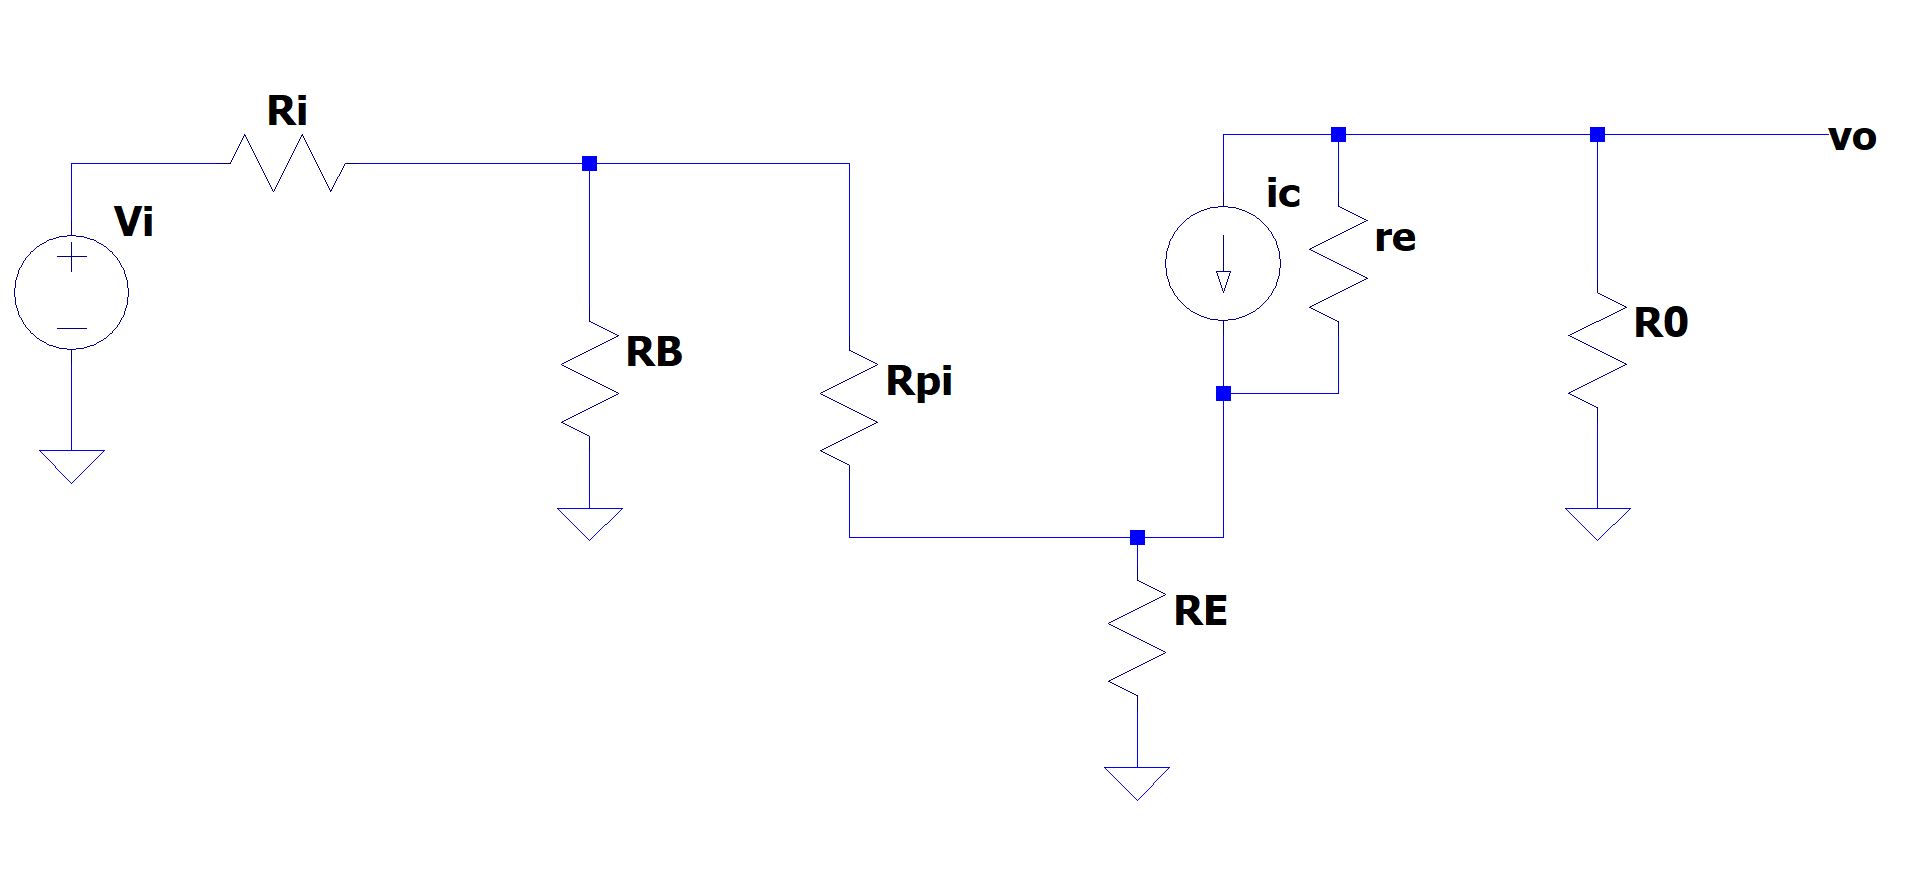

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

Ri = 600; %valor de entrada da figura 1

RC = 3.6e+3;%valor de entrada da figura 1
RB = Rth; %calculado
R0 = RC%calculado R0

R0 = 3600

RE = 180; %valor de entrada da figura 1  R2
VT = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q
vi = 10e-3

vi = 0.0100

### calculo do re e rpi:

re = VT/Ie

re = 20.0641

rpi = (B+1)*re

rpi = 5.8387e+03

### **Calculo para CA**

Zb = (B+1)*(RE+re)

Zb = 5.8219e+04

vb = (((1/RB)+(1/Zb))^-1/(Ri+((1/RB)+(1/Zb))^-1))*vi

vb = 0.0074

ib = vb/Zb

ib = 1.2789e-07

ic = B*ib

ic = 3.7089e-05

ie = (-vb+rpi*ib)/RE

ie = -3.7217e-05

Av = -B*((R0)/(Ri+((Ri/RB)+1)*(B+1)*(RE+re)))

Av = -13.3522

vo = Av*vi

vo = -0.1335

Z0 = R0

Z0 = 3600

ve = RE*ie

ve = -0.0067

vc=vo

vc = -0.1335

Zi = Ri+((1/RB)+(1/rpi))^-1

Zi = 1.9778e+03